clear all
addpath('time');

## Periodic motion propagation (Earth orbit)

Initial conditions:

a=46000;
time_sim=2*pi*sqrt((a^3)/astroConstants(13));
e=0.5;
n=sqrt(astroConstants(13)/(a^3));
teta_0=0;
k= -83.33333; %to change the size of the regular orbit

k = -83.3333

dteta_k=(n*(1+e*cos(teta_0))^2)/((1-e^2)^1.5)*k;
init_conds=[0 dteta_k*(((1+e)^0.5)*((1-e)^1.5))/((-n)*(2+e)) dteta_k 0];

Run Simulink:

sim_out=sim('relative_dynamics.slx');

Plot

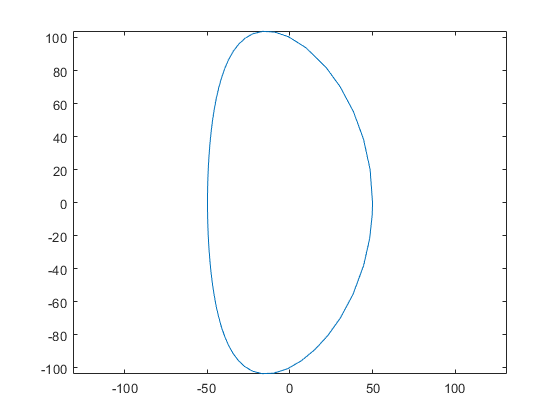

x=sim_out.simout.data(:,2);
y=sim_out.simout.data(:,4);
plot(x,y);
axis equal

## Periodic motion propagation (Asteroid)

clear all
a=1.4*astroConstants(2);
time_sim=2*pi*sqrt((a^3)/astroConstants(4));
e=0.5;
n=sqrt(astroConstants(4)/(a^3));
teta_0=0;
k= 100;%-83.33333 %to change the size of the regular orbit
dteta_k=(n*(1+e*cos(teta_0))^2)/((1-e^2)^1.5)*k;
init_conds=[0 dteta_k*(((1+e)^0.5)*((1-e)^1.5))/((-n)*(2+e)) dteta_k 0];

Run Simulink:

sim_out_SK=sim('relative_dynamics.slx');

Plot

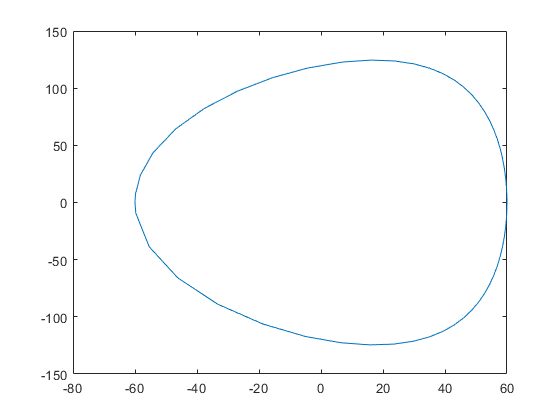

x=sim_out_SK.simout.data(:,2);
y=sim_out_SK.simout.data(:,4);
plot(x,y);

## Station keeping (20km,0km) (Asteroid)

clear all
a=1.4*astroConstants(2);
time_sim=3600%2*pi*sqrt((a^3)/astroConstants(4));

time_sim = 3600

e=0.5;
n=sqrt(astroConstants(4)/(a^3));
teta_0=deg2rad(180);
k= 100;%-83.33333 %to change the size of the regular orbit
dteta_k=(n*(1+e*cos(teta_0))^2)/((1-e^2)^1.5)*k;
reference_conds=[-20,0]

reference_conds =    -20     0


init_conds=[0 -20 0 0];

Run Simulink:

sim_out_DC_SK=sim('relative_DC_SK.slx');

Plot

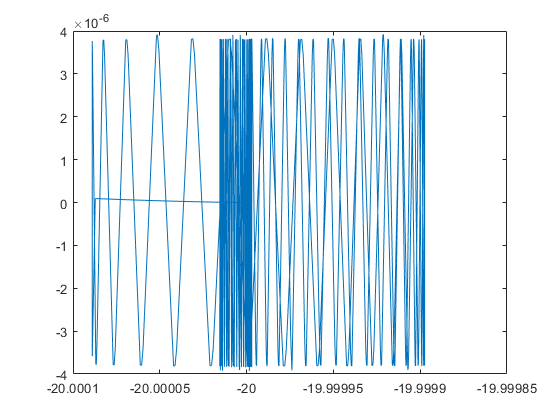

x=sim_out_DC_SK.simout.data(:,2);
y=sim_out_DC_SK.simout.data(:,4);
plot(x,y);